## TASK 3 EXERCICE1

MC = 1e5;          % Monte Carlo runs
sigma0 = 1;        % std under H0
sigma1 = sqrt(10); % std under H1
gamma = 1.96;      % threshold computed from theory

% Under H0 
x0 = sigma0 * randn(MC,1); 
decide_H1_H0 = abs(x0) >= gamma; 
PFA_emp = mean(decide_H1_H0);   % empirical P_FA

% Under H1 
x1 = sigma1 * randn(MC,1);
decide_H1_H1 = abs(x1) >= gamma;
PD_emp = mean(decide_H1_H1);    % empirical P_D

% Print results
fprintf('Empirical P_FA = %.4f\n', PFA_emp);

Empirical P_FA = 0.0500


fprintf('Empirical P_D  = %.4f\n', PD_emp);

Empirical P_D  = 0.5330



% Theoretical values 
P_FA_th = 2 * qfunc(gamma/sigma0);
P_D_th  = 2 * qfunc(gamma/sigma1);


## FIGURE

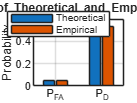

% Ploting for better understanding 
figure;
bar([P_FA_th, PFA_emp; P_D_th, PD_emp]);
set(gca, 'XTickLabel', {'P_{FA}', 'P_{D}'})
legend('Theoretical','Empirical');
ylabel('Probability');
title('Comparison of Theoretical and Empirical P_{FA} and P_{D}');
grid on;